*Naysla Tatiana Torres Cortes - *Ariel David Herrera Ahumada.

* Análisis numérico*

**ECUACIÓN CUADRÁTICA**

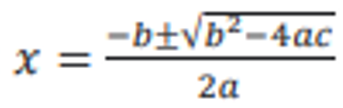

%Teniendo en cuenta que la ecuación a resolver es ((4*x)^2)+(2*x)-8
%Capturar las variables
clc
clear
close all
a=0;
fprintf('Evaluar la funcion: (4*x^2)+(2*x)-8')

Evaluar la funcion: (4*x^2)+(2*x)-8

%a no puede ser cero
while(a==0)
    prompt2 = 'Ingrese valor de a ';
    a = input(prompt2)
end

a = 4

prompt1 = 'Ingrese valor de b ';
b = input(prompt1)

b = 2

prompt3 = 'Ingrese valor de c ';
c = input(prompt3)

c = -8


x1= Raiz1(b,a,c);
x2= Raiz2(b,a,c);
fprintf('Raiz x1: '); disp(x1)

Raiz x1:     1.1861



fprintf('Raiz x2: '); disp(x2)

Raiz x2:    -1.6861




%Evaluar la funcion con las raices encontradas, puntos de corte con x
%teniendo en cuenta el intervalo [0,3]
y=ExpresionAlgebraica(b,a,c,x1);
strcat('Punto de corte 2 [',num2str(x1),',',num2str(y),']')

ans = 'Punto de corte 2 [1.1861,0]'

y=ExpresionAlgebraica(b,a,c,x2);
strcat('Punto de corte 3 [',num2str(x2),',',num2str(y),']')

ans = 'Punto de corte 3 [-1.6861,0]'

y=ExpresionAlgebraica(b,a,c,3);
strcat('Punto de corte 4 [3,',num2str(y),']')

ans = 'Punto de corte 4 [3,34]'

y =ExpresionAlgebraica(b,a,c,0);
strcat('Punto de corte 5 [0,',num2str(y),']')

ans = 'Punto de corte 5 [0,-8]'

v=VerticeParabola(b,a);
y =ExpresionAlgebraica(b,a,c,v);
strcat('Vertice de la parabola [',num2str(v),',',num2str(y),']')

ans = 'Vertice de la parabola [-0.25,-8.25]'

p=0;
%Evaluar la funcion en el intervalon [0,3] genera los siguientes puntos d
%ecorte
x=-3:0.001:3;
for (v = 3.0:-0.1:0.0)
   disp(v);
   p=p+1;
   y=ExpresionAlgebraica(b,a,c,v);
   strcat('Iteración_',num2str(p),' [',num2str(v),' , ',num2str(y),']')
end

     3



ans = 'Iteración_1 [3 ,34]'

    2.9000



ans = 'Iteración_2 [2.9 ,31.44]'

    2.8000



ans = 'Iteración_3 [2.8 ,28.96]'

    2.7000



ans = 'Iteración_4 [2.7 ,26.56]'

    2.6000



ans = 'Iteración_5 [2.6 ,24.24]'

    2.5000



ans = 'Iteración_6 [2.5 ,22]'

    2.4000



ans = 'Iteración_7 [2.4 ,19.84]'

    2.3000



ans = 'Iteración_8 [2.3 ,17.76]'

    2.2000



ans = 'Iteración_9 [2.2 ,15.76]'

    2.1000



ans = 'Iteración_10 [2.1 ,13.84]'

     2



ans = 'Iteración_11 [2 ,12]'

    1.9000



ans = 'Iteración_12 [1.9 ,10.24]'

    1.8000



ans = 'Iteración_13 [1.8 ,8.56]'

    1.7000



ans = 'Iteración_14 [1.7 ,6.96]'

    1.6000



ans = 'Iteración_15 [1.6 ,5.44]'

    1.5000



ans = 'Iteración_16 [1.5 ,4]'

    1.4000



ans = 'Iteración_17 [1.4 ,2.64]'

    1.3000



ans = 'Iteración_18 [1.3 ,1.36]'

    1.2000



ans = 'Iteración_19 [1.2 ,0.16]'

    1.1000



ans = 'Iteración_20 [1.1 ,-0.96]'

     1



ans = 'Iteración_21 [1 ,-2]'

    0.9000



ans = 'Iteración_22 [0.9 ,-2.96]'

    0.8000



ans = 'Iteración_23 [0.8 ,-3.84]'

    0.7000



ans = 'Iteración_24 [0.7 ,-4.64]'

    0.6000



ans = 'Iteración_25 [0.6 ,-5.36]'

    0.5000



ans = 'Iteración_26 [0.5 ,-6]'

    0.4000



ans = 'Iteración_27 [0.4 ,-6.56]'

    0.3000



ans = 'Iteración_28 [0.3 ,-7.04]'

    0.2000



ans = 'Iteración_29 [0.2 ,-7.44]'

    0.1000



ans = 'Iteración_30 [0.1 ,-7.76]'

     0



ans = 'Iteración_31 [0 ,-8]'

%Creacion de un arreglo para evaluar la funcion y grafica
fprintf('Parabola completa ')

Parabola completa 

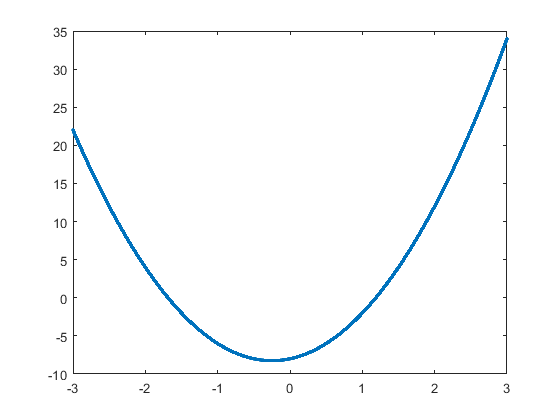

y=(4*x.^2)+(2*x)-8;
plot(x,y,'.')

fprintf('Parabola en el intervalo [0,3] ')

Parabola en el intervalo [0,3] 

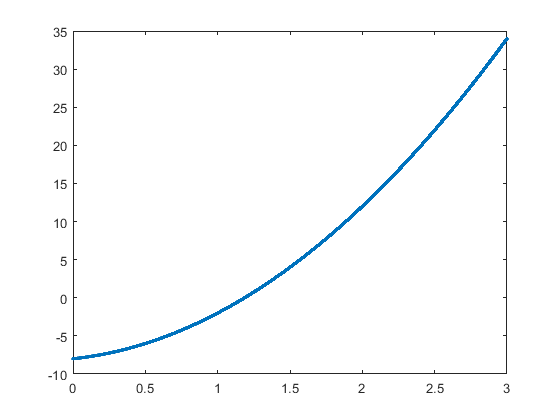

x=0:0.001:3;
y=(4*x.^2)+(2*x)-8;
plot(x,y,'.')


%Funciones
function [e] = ExpresionAlgebraica(b,a,c,x)   
   e = a*(x^2)+(b*x)+c;
end
function r1= Raiz1(b,a,c)
   %Evalua la raiz sumando           
   r1= (-b + sqrt(b^2-4*a*c))/(2*a);     
end
function r2= Raiz2(b,a,c)
   %Evalua la raiz restando           
   r2= (-b - sqrt(b^2-4*a*c))/(2*a);     
end
function v= VerticeParabola(b,a)
   %Hallar vertice           
   v= -b/(2*a);     
end